# Weight Loss Dataset

This data was collected from a crowd sourced experiment looking at the effects of various parameters on weight loss. Data was gathered through the use of self-tracking apps (such as activity trackers like FitBit™ or through questionnares. The study lasted 3 months and the values present here have been aggregaged and patients with missing data have been dropped along with any potentially identifiable information. Our overall goal is to find which parameters are most associated with wieght loss.

## Dataset Description

The data is given in a sqlite datbase named **wightdata.sqlite**, with a single table, **patient**. 

- `age` Patient's age at the start of the study

- `gender` self-identified gender

- `height` the patient's height (in inches)

- `initweight` the weight of the patient at the start of the study (in pounds)

- `calintake` the average number of calories consumed by day

- `jobstatus` the self-identified job status, either Active or Inactive

- `timecardio` the average minutes of cardio (per week)

- `timeresist` the average minutes of resistance training (per week)

- `sleep` the average amount of sleep (hours) per day

- `steps` the average number of steps per day (counted using phone accelerometers)

- `deltaweight`the change in weight after the 3-month study (in pounds)

## Variable names

- `data` All patient data, represented as a MATLAB table object

## Objectives

- Understand the dataset

- Be able to manipulate the database tables in the DB Browser for SQlite

- Connection to the dataset using MATLAB functions, native connection, and JDBC.

- Use SQL query in MATLAB; import data to a cell array, convert a cell array to a table, and convert a cell array to a matrix

- Be able to manipulate the data in a cell array, table, and matrix

- Logical Index Array

- `corrcoef() `[https://www.mathworks.com/help/matlab/ref/corrcoef.html#bunkanr](https://www.mathworks.com/help/matlab/ref/corrcoef.html#bunkanr)

- Two-sample t-test; MATLAB *ttest2* [`[h,p,ci,stats] = ttest2(``___``)`](https://www.mathworks.com/help/stats/ttest2.html#d117e865369)

- Combine variables to test a new model

- Multivariate linear regression, `mvregress()`

- `Z-scaling`

# Connect to the Database

% Establish connection to JDBC data source
conn = database('hw5_weightdata', '', '');

# Data Statistics Using SQL

**Use SQL queries to answer each of the following questions.**

% Establish sql query of 'SELECT * FROM patient'
% Use fetch to import data to dbdata (as a cell array)
% Use cell2table() to convert the cell array dbdata to a table as data
% assigning the following column names (VariableNames)
% 'id' 'age' 'gender' 'height' 'initweight' 'calintake' 'jobstatus'
% 'timecardio' 'timeresist' 'sleep' 'steps' 'deltaweight' 
query = 'SELECT * FROM patient';
dbdata = fetch(conn, query, 'DataReturnFormat', 'cellarray')

dbdata = 250×12 cell array
    {[ 1]}    {[19]}    {'Female'}    {[59.3734]}    {[137.1087]}    {[1.9678e+03]}    {'Inactive'}    {[39.1656]}    {[ 3.5163]}    {[9.0446]}    {[3.3119e+03]}    {[ 0.1447]}
    {[ 2]}    {[19]}    {'Female'}    {[82.6719]}    {[154.9608]}    {[1.8850e+03]}    {'Inactive'}    {[37.6153]}    {[ 1.2296]}    {[8.7172]}    {[3.6939e+03]}    {[ 8.1381]}
    {[ 3]}    {[37]}    {'Female'}    {[61.0149]}    {[132.0130]}    {[      1500]}    {'Active'  }    {[38.3226]}    {[ 0.4893]}    {[9.3964]}    {[3.1937e+03]}    {[-3.1881]}
    {[ 4]}    {[36]}    {'Female'}    {[62.4880]}    {[129.7659]}    {[1.7951e+03]}    {'Inactive'}    {[36.2942]}    {[ 9.0963]}    {[8.6012]}    {[2.9419e+03]}    {[ 2.4569]}
    {[ 5]}    {[32]}    {'Female'}    {[59.1823]}    {[132.2316]}    {[      1500]}    {'Active'  }    {[36.5790]}    {[ 0.6230]}    {[8.5469]}    {[3.6457e+03]}    {[ 0.6059]}
    {[ 6]}    {[38]}    {'Male'  }    {[62.5520]}    {[187.9075]}    {[1.7481e+03]}    {

% Convert data to a table with specific column headers
cols = {'id', 'age', 'gender', 'height', 'initweight', 'calintake', 'jobstatus', 'timecardio',...
	      'timeresist', 'sleep', 'steps', 'deltaweight'};
data = cell2table(dbdata, "VariableNames", cols)

data = 250×12 table
    id    age      gender      height    initweight    calintake     jobstatus      timecardio    timeresist    sleep     steps     deltaweight
    __    ___    __________    ______    __________    _________    ____________    __________    __________    ______    ______    ___________
     1    19     {'Female'}    59.373      137.11       1967.8      {'Inactive'}      39.166        3.5163      9.0446    3311.9      0.14471  
     2    19     {'Female'}    82.672      154.96         1885      {'Inactive'}      37.615        1.2296      8.7172    3693.9       8.138

# Active Versus Inactive & Average Age Difference between Active and Inactive

**How many patients have "Active" jobstatus, and how many are "Inactive"?**

% Use SQL query to get the number of 'Active' and 'Inactive' patients
query = 'SELECT jobstatus, COUNT(jobstatus) FROM patient GROUP BY jobstatus';
num_jobstatus = fetch(conn, query)

num_jobstatus = 2×2 table
     jobstatus      COUNT_jobstatus_
    ____________    ________________
    {'Active'  }          129       
    {'Inactive'}          121       

# Average Age of Patients with Active & Inactive `jobstatus`

`What is the average age of the patients with Active & Inactive jobstatus`

% Use SQL query to get the average age of patients in the different groups
query = 'SELECT jobstatus, AVG(age) FROM patient GROUP BY jobstatus';
fetch(conn, query)

ans = 2×2 table
     jobstatus      AVG_age_
    ____________    ________
    {'Active'  }     33.023 
    {'Inactive'}     32.884 

% Alternatively, use a cell array to compute the means
means = splitapply(@mean, [dbdata{:,strcmpi(cols, 'age')}]', findgroups(dbdata(:,strcmp(cols, 'jobstatus'))));
fprintf(['The mean age of Active patients was %.2f years.\n' ...
	       'The mean age of Inactive patients was %.2f years.'], means)

The mean age of Active patients was 33.02 years.
The mean age of Inactive patients was 32.88 years.

# Gender-Specific Differences in Exercise Preference

Use the data to answer whether there ae gender-specific differences in exercise preference (resistance vs cardio) and whether the subject does ANY exercise. Remember to not include patiemts with missing exercise information in the analysis.

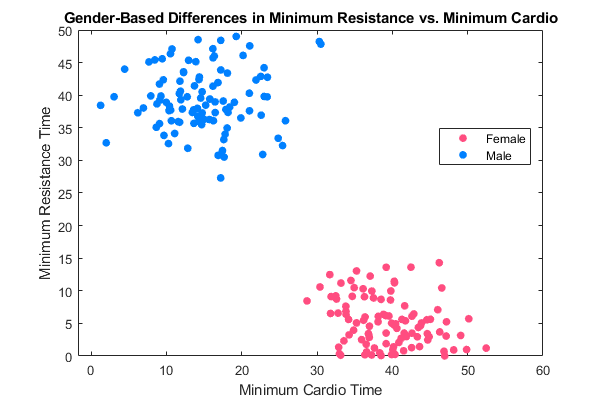

% Create mask for patients with no exercise
I = (data.timecardio == 0) | (data.timeresist == 0);

% Initiate figure
figure('Position', [0 0 600 400]);
% Create a scatter plot comparing timecardio and timeresist for patients
% who exercised grouped by gender
gscatter(data.timecardio(~I), data.timeresist(~I), data.gender(~I), [1 .3 .5; 0 .5 1], [], [20 20]);
xlabel('Minimum Cardio Time');
ylabel('Minimum Resistance Time');
title('Gender-Based Differences in Minimum Resistance vs. Minimum Cardio')

#### **Gender Figure Caption:**

This figure shows the minimum time spent resistance training plotted against the minimum time spent doing cardio for all the patients involved in the study. The pink data points are female patients and the blue data points are male.

#### **Gender Figure Conclusion:**

The figure shows clear separation between the male and female patients. Female patients spend significantly more time on cardio training that they do on resistance training. The reverse is true for male patients. Therefore, we can conclude that female patients had a preference for cardio while male patients had a preference for resistance training.

# **Differences between Job Status**

Use the data (box plots) to answer whether the job status influences the average number of steps a subject takes per day and the average number of calories consumed. Does job status affect the initial weight?

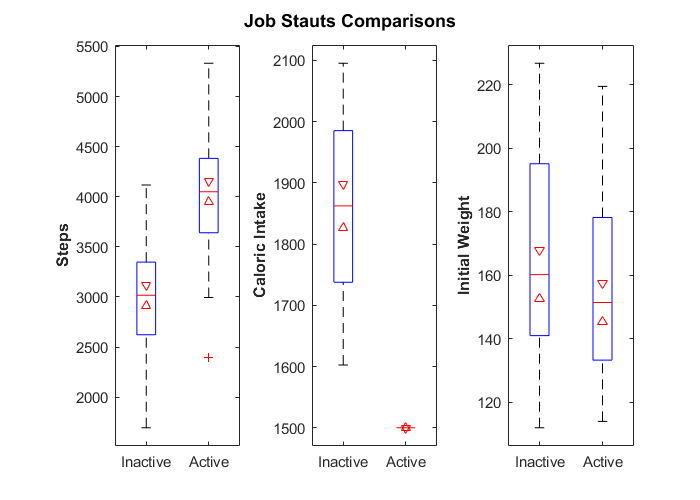

% Create the Job Status figure

% Create plots in 1-by-3 subplot grid
figure('Position', [0 0  700 500]);
sgtitle('Job Stauts Comparisons', 'FontWeight', 'bold')

% Create Boxplot: steps
subplot(1,3,1);
boxplot(data.steps, data.jobstatus, 'Notch', 'marker');
set(gca, 'FontSize', 11);
ylabel('Steps', 'FontWeight', 'bold', 'FontSize', 12);

% Create Boxplot: caloric intake
subplot(1,3,2);
boxplot(data.calintake, data.jobstatus, 'Notch', 'marker');
set(gca, 'FontSize', 11);
ylabel('Caloric Intake', 'FontWeight', 'bold', 'FontSize', 12);

% Create Boxplot: Initial Weigh
subplot(1,3,3);
boxplot(data.initweight, data.jobstatus, 'Notch', 'marker');
set(gca, 'FontSize', 11);
ylabel('Initial Weight', 'FontWeight', 'bold', 'FontSize', 12);

#### **Jobstatus Figure Caption:**

The figure shows boxplots comparing *Steps *(first from left)*, Caloric Intake *(second from left)*, *and *Initial Weight *(last from left) in active and inactive patients. The red lines indicate the medians of each group, the triangular notches indicate the comparison interval at the 5% significance level; two groups are significantly different if their comparison intervals do not overlap.

#### **Jobstatus Figure Conclusion:**

We can conclude that there is a significant difference in *Steps* and *Caloric Intake* between active and inactive patients. Active patients had a higher step count, and a remarably lower caloric intake, while incative patients had a lower step count, and a higher caloric intake. There was no significant difference between the initial weight of active and inactive patients.

# Effects of Sleep

Plenty of research has shown that sleep is important for weight loss. Use this data to explore this question. Is it correlated with the weight change? Is it different between genders or job statuses (active or inactive)? Is it correlated with anything else in this dataset?

### What Variables are Significantly Correlated with Sleep, and Why?

% Select columns to test for correlation
cols = {'sleep', 'age', 'height', 'initweight', 'deltaweight',...
	      'calintake', 'timecardio', 'timeresist', 'steps'};
% Compute correlation coefficients and p-values
[R, p] = corrcoef(data{:, cols});
% Show variables that correlated significantly with sleep (alpha = 0.01)
sig = find(p(1, :) < .01);
for i = 1:numel(sig)
	fprintf( '%s is correlated significantly with sleep (R^2 = %.4f, p = %.2e) \n',...
		       cols{sig(i)}, R(1, sig(i))^2, p(1, sig(i)) )
end

deltaweight is correlated significantly with sleep (R^2 = 0.0438, p = 8.74e-04) 
steps is correlated significantly with sleep (R^2 = 0.0278, p = 8.21e-03) 


Sleep seems to be correlated significantly with weight loss (`deltaweight) and steps.`

### Does Job Status Affect Sleep, and Why?

% Create mask for active patients
I = strcmp(data.jobstatus, 'Active');

% Run T-Tests for sleep in active & inactive patients
myttest(data.sleep, I, 'amount of sleep gotten', 'active and inactive');

The amount of sleep gotten by active and inactive patients is not significantly different (p = 2.3634e-01).


The patient job status does not affect sleep since there is no significant difference between the amount of sleep gotten by the groups.

### Does Gender Affect Sleep, and Why?

% Create mask for male patients
I = strcmp(data.gender, 'Male');

% Run T-Tests for sleep in male & female patients
myttest(data.sleep, I, 'amount of sleep gotten', 'male and female');

The amount of sleep gotten by male and female patients is not significantly different (p = 2.9769e-01).


The patient gender does not affect sleep since there is no significant difference between the amount of sleep gotten by the groups.

### A Scatter Plot Comparing Sleep with deltaWeight and Steps

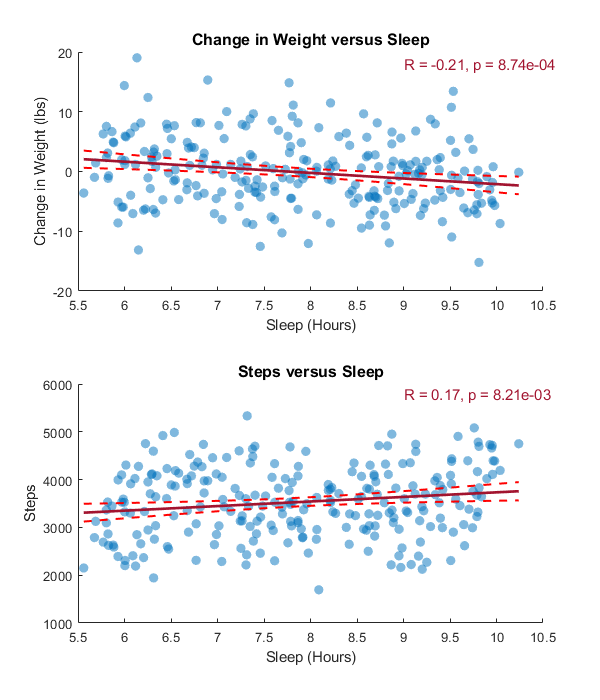

figure('Position', [0 0 600 700]); 

% A scatter plot between sleep and deltaweight
subplot(2,1,1); 
hold on;
scatter(data.sleep, data.deltaweight, 50, 'filled',...
	      'MarkerFaceColor', '#0072BD', 'MarkerFaceAlpha', 0.5);
xlabel('Sleep (Hours)', 'FontSize', 11);
ylabel('Change in Weight (lbs)', 'FontSize', 11);
title('Change in Weight versus Sleep', 'FontSize', 12, 'FontWeight', 'bold');
% Fit data to a linear regression model
mdl = fitlm(data.sleep, data.deltaweight);
% Compute confidence intervals and trendline
[trend, ci] = predict(mdl, sort(data.sleep));
% Add trendline and confidence intervals to figure
plot(sort(data.sleep), trend, '-', 'Color', '#A2142F', 'LineWidth', 2);
plot(sort(data.sleep), ci, '--r', 'LineWidth', 1.5);
hold off;
% Show R^2 and p values on figure
[R, p] = corrcoef(data.sleep, data.deltaweight);
text(9, 18, sprintf('R = %.2f, p = %.2e', R(2), p(2)),...
	   'Color', '#A2142F', 'FontSize', 11)

% A scatter plot between sleep and steps
subplot(2,1,2); hold on;
scatter(data.sleep, data.steps, 50, 'filled',...
	      'MarkerFaceColor', '#0072BD', 'MarkerFaceAlpha', 0.5);
xlabel('Sleep (Hours)', 'FontSize', 11);
ylabel('Steps', 'FontSize', 11);
title('Steps versus Sleep', 'FontSize', 12, 'FontWeight', 'bold');
% Fit data to a linear regression model
mdl = fitlm(data.sleep, data.steps);
% Compute confidence intervals and trendline
[trend, ci] = predict(mdl, sort(data.sleep));
% Add trendline and confidence intervals to figure
plot(sort(data.sleep), trend, '-', 'Color', '#A2142F', 'LineWidth', 2);
plot(sort(data.sleep), ci, '--r', 'LineWidth', 1.5);
hold off;
% Show R^2 and p values on figure
[R, p] = corrcoef(data.sleep, data.steps);
text(9, 5800, sprintf('R = %.2f, p = %.2e', R(2), p(2)),...
	   'Color', '#A2142F', 'FontSize', 11)

#### Sleep Figure Caption

This figure shows scaterplots showing the relationship between the amount of sleep gotten by patients (`sleep`) and the weight loss experienced (`deltaweight`) and the amount of steps they take (`steps`). The data is represented by the blue points. The red solid lines are trendlines fitted by least squares regression, and the red dashed lines are confidence intervals.The scatter plots are overlayed with the correlation coefficient, $R$, and $p-value$ of the correlations.

#### Sleep Figure Conclusions

There is a weak, statistically significant negative correlation between weight loss and sleep, indicating that more sleep tends to lead to greater weight loss (-ve change in weight). The is also a weak, statistically significant positive correlation between steps taken and amount of sleep; indicating that more steps is correlated with more sleep.

# Combining Values to Calculate Net Calories and Compare with Weight Loss

We talked previously about inter-correlations between features when building linear models. We know that gender has effects on exercise preference and jobtype affects the number of steps. One way to alleviate those issues is to use domain knowledge to create summary values. We know from biology that what's really important for weight loss is creating a calorie deficit. We know from the data how many calories they consumed but now how much they expended.

Basal calorie and execise calorie

basal - calories burned when not active

execise - calories burned when active

% Equation for Calculation Basal Metabolic Rate (BMR)
% BMR as a function of parameters we measured.

% BMR calculation for men (metric)
% BMR = 66.47 + ( 13.75 x weight in kg ) + ( 5.003 x height in cm ) - ( 6.755 x age in years )
% BMR = 66.47 + ( 13.75 * 0.4536 * weight in lbs ) + 
%               ( 5.003 * 2.54 * height in inches ) - 
%               ( 6.755 x age in years )

% BMR calculation for women (metric)
% BMR = 655.1 + ( 9.563 x weight in kg ) + ( 1.850 x height in cm ) - ( 4.676 x age in years )
% BMR = 655.1 + ( 9.563 * 0.4536 * weight in lbs ) + 
%               ( 1.850 * 2.54 * height in inches ) - 
%               ( 4.676 x age in years )

% Reference: Harris JA, Benedict FG. A biometric study of human basal metabolism. 
%            Proc Natl Acad Sci USA 1918;4(12):370-3. 
% Website: http://www.globalrph.com/harris-benedict-equation.htm

% Define lambda functions for computing BMR for each gender
mBMR = @(w,h,a) 66.47 + 13.75*.4536*w + 5.003*2.54*h - 6.755*a;
fBMR = @(w,h,a) 655.1 + 9.563*.4536*w + 1.850*2.54*h - 4.676*a;

% Preallocate BMR column
data.BMR = zeros(height(data), 1);
% Calculate the BMR for male patients
I = strcmp(data.gender, 'Male');
data.BMR(I) = mBMR(data.initweight(I), data.height(I), data.age(I));
% Calculate the BMR for female patients
I = strcmp(data.gender, 'Female');
data.BMR(I) = fBMR(data.initweight(I), data.height(I), data.age(I));

% Google around and find estimates for the amount of calories burned during
% aerobic exercise and resistance exercise.

% average age used to determine calories burned per hour
fprintf('The average weight of the patients is %.2flbs', mean(data.initweight))

The average weight of the patients is 161.47lbs

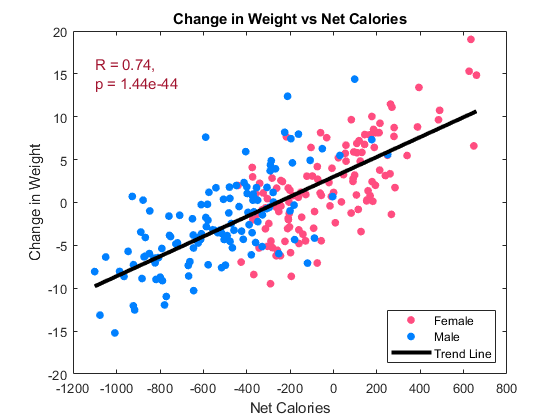

%   Resistance Training: 422 cal/hour
%   High Impact Aerobics: 493 cal/hour
% Reference: Calories burned during exercise, activities, sports and workouts. (n.d.). 
%            Retrieved October 31, 2021, from https://www.nutristrategy.com/caloriesburned.htm. 

% Compute the total exercise calories (resistance calories + cardio calories)
data.calexercise = (data.timeresist * 422/60) + (data.timecardio * 493/60);

% Calculate the net calorie change 
% Net Cal = Cal Intake - Exercise Cal - Basal Cal
data.netcal = data.calintake - data.calexercise - data.BMR;

% Create Change in Weight vs Net Calories Figure
figure;
gscatter(data.netcal, data.deltaweight, data.gender, [1 .3 .5; 0 .5 1], [], [20 20]);
xlabel('Net Calories');
ylabel('Change in Weight');
title('Change in Weight vs Net Calories')
% Fit data to a linear regression model
mdl = fitlm(data.netcal, data.deltaweight);
% Compute trendline
trend = predict(mdl, sort(data.netcal));
% Add trendline and confidence intervals to figure
hold on; plot(sort(data.netcal), trend, '-k', 'LineWidth', 3); hold off;
% Show R^2 and p values on figure
[R, p] = corrcoef(data.netcal, data.deltaweight);
text(-1100, 15, sprintf('R = %.2f,\np = %.2e', R(2), p(2)),...
	   'Color', '#A2142F', 'FontSize', 11)
legend({'Female', 'Male', 'Trend Line'}, 'Location', 'southeast')

### Figure Caption

This figure is a scatter plot showing the change in weight plotted against the net calories burned by the patients. The pink data points are female patients, and the blue data points are male patients. The trend line shows the correlatiion between the variables. The figure is also overlayed with the $R$ and $p$-values.

### Conclusions

There is a strong, statistically significant positive correlation between net calories and weight loss. This indicates that calorie loss is strongly correlated with, and is a fairly good predictor of weight loss $\left(R^2=0.55\right)$. Also, male patients tended to exhibit more weight loss (and net calorie change) than female patients as evidenced by the point separation in the figure.

# Build a Model

Use all of this information to build the best model to predict the change in weight for each subject. Plot your predictions versus reality. Calculate the R^2 and discuss what it implies. Discuss the effect sizes and their relevance to weight loss.

## Practice `corrcoef()` and `ttest2()`

% Determine what variables are significantly correlated with change in
% weight.
% Select columns to test for correlation
cols = {'deltaweight', 'netcal', 'sleep', 'steps', 'age', 'height', 'initweight',...
	      'calintake', 'timecardio', 'timeresist'};
% Compute correlation coefficients and p-values
[R, p] = corrcoef(data{:, cols});
% Show variables that correlated significantly with sleep (alpha = 0.01)
sig = find(p(1, :) < .01);
for i = 1:numel(sig)
	fprintf('%s is correlated significantly with weight loss (R^2 = %.4f, p = %.2e) \n',...
		       cols{sig(i)}, R(1, sig(i))^2, p(1, sig(i)) )
end

netcal is correlated significantly with weight loss (R^2 = 0.5473, p = 1.44e-44) 
sleep is correlated significantly with weight loss (R^2 = 0.0438, p = 8.74e-04) 
height is correlated significantly with weight loss (R^2 = 0.0921, p = 1.01e-06) 
initweight is correlated significantly with weight loss (R^2 = 0.0557, p = 1.65e-04) 
calintake is correlated significantly with weight loss (R^2 = 0.1787, p = 2.96e-12) 
timeresist is correlated significantly with weight loss (R^2 = 0.2903, p = 3.18e-20) 


### Does Job Status Affect Weight Loss?

% Create mask for active patients
active = strcmp(data.jobstatus, 'Active');

% Run T-Tests for sleep in active & inactive patients
myttest(data.deltaweight, active, 'weight loss', 'active and inactive');

The weight loss by active and inactive patients is significantly different (p = 1.8546e-08).


### Does Gender Affect Weight Loss?

% Create mask for male patients
male = strcmp(data.gender, 'Male');

% Run T-Tests for sleep in active & inactive patients
myttest(data.deltaweight, male, 'weight loss', 'male and female');

The weight loss by male and female patients is significantly different (p = 1.7937e-10).


Of the variables tested, 6 showed a significant correlation with weight loss, and 2 (job status and gender) had a significant impact on weight loss. These eight variables will be included in the multivariate regression model.

### Multivariate Normal Regression

`mvregress(X,Y)` returns the estimated coefficients for a [multivariate normal regression](https://www.mathworks.com/help/stats/mvregress.html#btkr6ds-3) of the *d*-dimensional responses in Y on the design matrices in X.

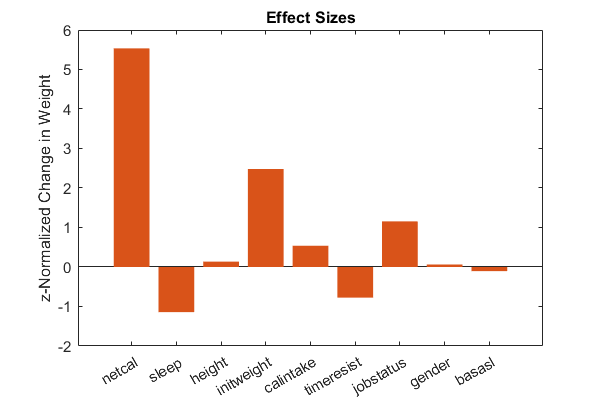

% Initialize the X variable to have 9 columns: netcal, sleep, height,
% initweight, calintake, timeresist, jobstatus, gender, and a ninth column
% containing just ones (Basal).
X = [data{:, {'netcal', 'sleep', 'height', 'initweight', 'calintake', 'timeresist'}},...
	   active, male, ones(height(data), 1)];
% Normalize X data for more accurate model fitting
X = normalize(X);
X(:, end) = 1;

% Initialize the Y variable to be change in weight
Y = data.deltaweight;

% Perform multivariate regression on the data
beta = mvregress(X, Y);

% Compute predictions
YPred = X * beta;

% Discuss the effect sizes and their relecance to weight loss
% Compare effect sizes
figure('Position', [0 0 600 400]);
bar(beta, 'FaceColor', '#D95319', 'LineStyle', 'none');
ylabel('z-Normalized Change in Weight', 'FontSize', 12);
title('Effect Sizes', 'FontSize', 14);
set(gca, 'xticklabel', {'netcal', 'sleep', 'height', 'initweight', 'calintake',...
	                      'timeresist', 'jobstatus', 'gender', 'basasl'}, 'FontSize', 11);

#### Effect Size Figure Caption

This figure is a barplot showing the effect size for the 9 different components of our multivariate regression model. The data was normalized beforehand so the bar heights represent the $z$-normalized change in weight for each of the different components.

#### Effect Size Figure Conclusion

The net calorie change appears to have lagest (positive) effect on change in weight, followed by the initial weight, amount of sleep gotten, job status, and time spent on resistance training.

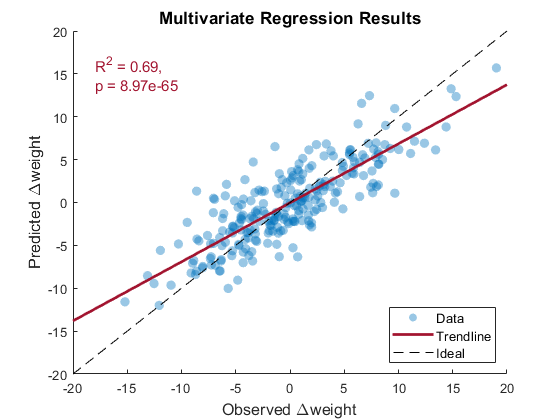


% Create scatter plot comparing observations and predictions
figure;
scatter(Y, YPred, 50, 'filled', 'MarkerFaceColor', '#0072BD', 'MarkerFaceAlpha', 0.4);
xlabel('Observed {\Delta}weight', 'FontSize', 12); 
ylabel('Predicted {\Delta}weight', 'FontSize', 12);
title('Multivariate Regression Results', 'FontSize', 13);
% Fit a trend line to the data
p = polyfit(Y, YPred, 1);
% Add trend line to data
hold on;
plot(-20:20, (-20:20)*p(1) + p(2), '-', 'LineWidth', 2, 'Color', '#A2142F');
plot(-20:20, -20:20, '--k');
hold off;
% Compute correlation between observed and predicted data
% Show R^2 and p values on figure
[R, p] = corrcoef(Y, YPred);
text(-18, 15, sprintf('R^2 = %.2f,\np = %.2e', R(2)^2, p(2)),...
	   'Color', '#A2142F', 'FontSize', 11);
% Add legend
legend({'Data', 'Trendline', 'Ideal'}, 'Location', 'southeast', 'FontSize', 10);

#### Model Figure Caption

This figure is a scatterplot showing the observed change in weight plotted against the change in weight predcted by our model. The data is represented by the blue dots. The black dashed line represents an ideal model - one that perfectly predicts the observed data. The red solid line is a trend line indicating the correlation between the predictions and observations.

#### Model Figure Conclusion

With $R^2=0.69$, our model appears to be a fairly good predictor of the actual weight loss experineced by patients in this study.

function myttest(x, I, ttxt, gtxt)
% This function runs ttests and prints out a statement about the results in
% the command line.
  % Input Arguments
	%   x -> numeric vector containing data to perform ttest on
	%   I -> logical vector used to select the two different groups
	%   gtxt -> string specifying groups (for printing in fprinf)
	[h,p] = ttest2(x(I), x(~I), 'Alpha', 0.01);
	if h
		fprintf(['The ' ttxt ' by ' gtxt ' patients is significantly different (p = %.4e).\n'], p)
	else
		fprintf(['The ' ttxt ' by ' gtxt ' patients is not significantly different (p = %.4e).\n'], p)
	end
end